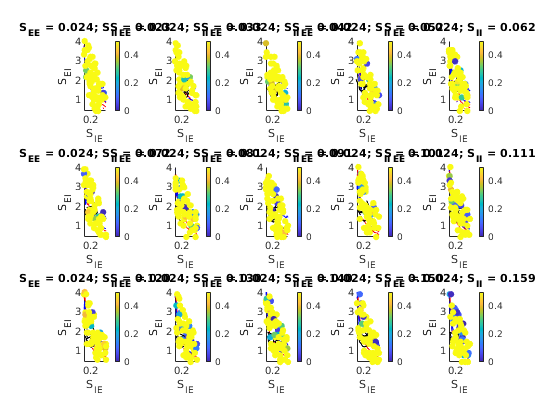

load('ContourData_S_EE=0.024_3D_rIamb540.mat','ContourData_3D');
load('ContourData_S_EE=0.024NWValidate_S_II_rEamb0.54_rIamb0.54_1.mat','ContourValidate');

figure('Name','3DPlot_FrCheck')
for plotInd = 1:length(ContourValidate.S_IItest)
Fr_MFComp = zeros(size( squeeze(ContourValidate.Fr_NW_Valid(:,:,plotInd)) ));

NWtestSeq = squeeze(ContourValidate.NWtestSeq3D(:,:,plotInd));
for FrInd = 1:size(Fr_MFComp,2)
    Fr_MFComp(:,FrInd) = ContourData_3D.Fr_NoFix(:,NWtestSeq(FrInd,1),NWtestSeq(FrInd,2), plotInd);    
end

Accuracy = abs(Fr_MFComp - squeeze(ContourValidate.Fr_NW_Valid(:,:,end)))./Fr_MFComp;
c = min(Accuracy);
c(isnan(c)) = 1;
c(isinf(c)) = 1;

subplot(3,5,plotInd)
hold on
    CurrentFrE = squeeze(ContourData_3D.Fr_NoFix(1,:,:,plotInd)); CurrentFrE(CurrentFrE<eps) = nan;
    CurrentFrI = squeeze(ContourData_3D.Fr_NoFix(2,:,:,plotInd)); CurrentFrI(CurrentFrI<eps) = nan;
    [C1,h1]= contour(ContourData_3D.S_IEtestMtp_of_S_II,ContourData_3D.S_EItest/ContourValidate.S_EE,...
                     CurrentFrE,[2 5],'ShowText','on','color','r');
    clabel(C1,h1,'FontSize',10,'Color','k')
    [C2,h2]= contour(ContourData_3D.S_IEtestMtp_of_S_II,ContourData_3D.S_EItest/ContourValidate.S_EE,...
                     CurrentFrI,[7 15],'ShowText','on','color','b');
    clabel(C2,h2,'FontSize',10,'Color','k')
    scatter(ContourData_3D.S_IEtestMtp_of_S_II(NWtestSeq(:,2)),...
            ContourData_3D.S_EItest(NWtestSeq(:,1))/ContourValidate.S_EE,...
            25,c,'filled')
hold off
colorbar
caxis([0, 0.5]);
xlabel('S_{IE}');ylabel('S_{EI}')
titletxt = sprintf('S_{EE} = %.3f; S_{II} = %.3f', ContourValidate.S_EE, ContourValidate.S_IItest(plotInd));
title(titletxt)

end